# **BMTS - Temperature Sensor Emulation with TSE**

This example shows you how to configure a Speedgoat Temperature Sensor Emulator (TSE), set each channel's resistance, and read back status information.

One TSE offers up to 36 independent and isolated channels for temperature sensor emulation. The stackable design allows the combination of one or multiple TSEs, Speedgoat Battery Cell Emulators (BCE) and Fault Insertion Units (FIU) to emulate and test large-scale battery packs and battery management systems (BMS) with temperature sensor emulation capability.

The Simulink model features the [BMTS Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_setup), [BMTS Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_read), [BMTS Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_write), and [BMTS Bus Pack](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bmts_buspack) blocks.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with a free Ethernet port

- Speedgoat Temperature Sensor Emulator

- Ethernet cable from the target machine to the TSE

### Test Setup

In this example, a TSE04-1000-1 with 4 channels is used. For devices with more channels, the configuration can be changed by following these steps:

- Open the [BMTS Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_setup) block, click the device type of device 1 in the table (**TSE04-1000-1**) to open a drop-down menu, and select a different device

- Click **Save and Close**

- Open the [BMTS Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_read) and [BMTS Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_write) block masks, select the new device from the drop-down menu, and click **OK**

- Open the [BMTS Bus Pack](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bmts_buspack) block and set the **Device Type** on the **Device Selection** tab to the correct device, then click **OK**

### Configuration

The Speedgoat real-time target machine communicates with the Speedgoat Temperature Sensor Emulator over EtherCAT. For this purpose, the Ethernet port of the target machine must be configured for EtherCAT.

Use a CAT5 cable or newer to connect the target machine and the TSE. On the target machine, choose an unused RJ45 Ethernet connector, an onboard interface or an IO71x/IO791 I/O module. Plug the other end of the cable into the upper RJ45 connector of the TSE, labeled with ETH1.

To activate EtherCAT support for the respective interface, enter the following in the MATLAB command window to open the Ethernet Configuration Tool:

Select **EtherCAT** in the **Configuration** column for the chosen interface, as shown below for the ETH1 interface:

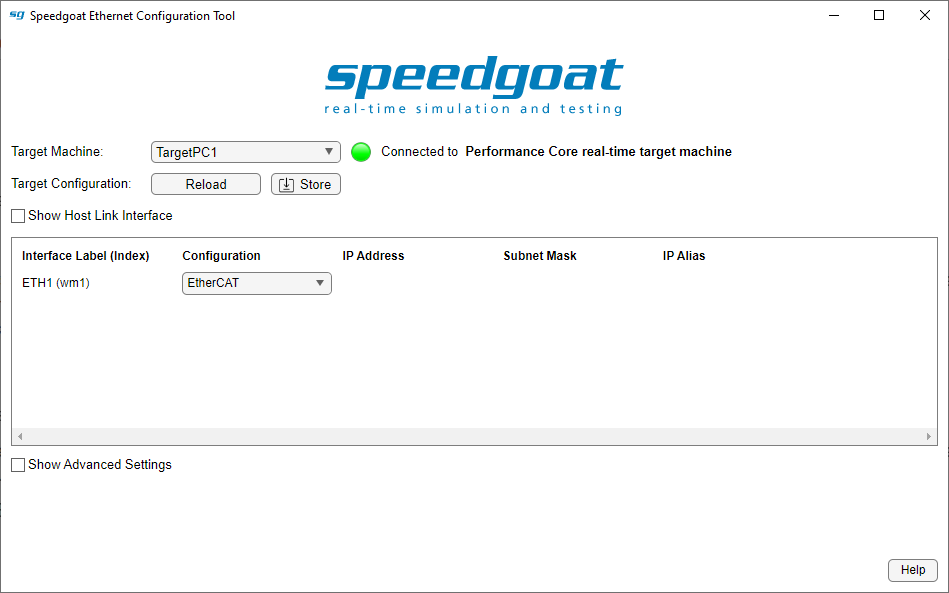

Click the **Store** button to store the configuration on the target machine, then close the Ethernet Configuration Tool when the process has finished.

## Open Simulink Model

 
modelName = 'sgMdl_BMTS_TemperatureSensorEmulationWithTSE';
open_system(modelName);         % Open Simulink model

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

Unrecognized function or variable 'modelName'.


% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Open the Simulation Data Inspector
Simulink.sdi.view;

% Start the real-time application
tg.setStopTime(60);
tg.start;

% Wait for the application to stop
while(strcmp(tg.status, 'running'))
    pause(1);
end

% Select the signals for plotting, set the axis limits and line colors
sdiRunIDs = Simulink.sdi.getAllRunIDs;
sdiLatestRun = Simulink.sdi.Run.getLatest;
s = sdiLatestRun.getSignalsByName('Ch1_Status'); s=s(1);
plotOnSubPlot(s,1,1,true);
s.LineColor = [0.6350 0.0780 0.1840];
s = sdiLatestRun.getSignalsByName('Ch2_Status'); s=s(1);
plotOnSubPlot(s,1,1,true);
s.LineColor = [0.8500 0.3250 0.0980];
s = sdiLatestRun.getSignalsByName('Ch3_Status'); s=s(1);
plotOnSubPlot(s,1,1,true);
s.LineColor = [0 0.4470 0.7410];
s = sdiLatestRun.getSignalsByName('Ch4_Status'); s=s(1);
plotOnSubPlot(s,1,1,true);
s.LineColor = [0.4940 0.1840 0.5560];
Simulink.sdi.setSubplotLimits(1,1,'AllRange',[0,60,-1,1050000]);

### Check the Results

Open the Simulink scope connected to the [BMTS Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_read) block and compare the signals to check if the resistance control is working as expected. On the scope, the status signal of channels 1-4 are displayed. Over the course of 60 seconds of simulation time, each channel's resistance is increased by 100,000 Ohm every 10 seconds, with an offset of 100,000 Ohm between the channels. The value of the status signal reports the actual resistance set at the output, taking into account the factory-calibrated resistance values of each channel's resistor ladder.

 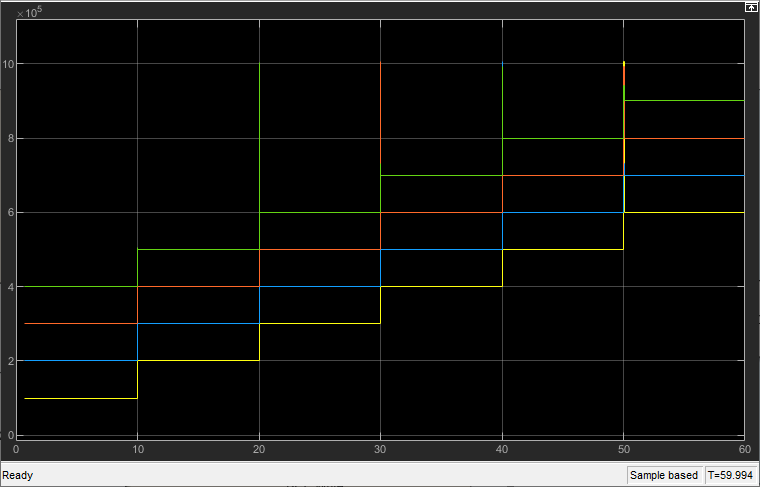

You can also see that when the resistance changes, the TSE switches through a temporary higher-resistance state. This is due to the "Close First" switching mode, and is recommended for electrical safety. Other switching modes are available in the [BMTS Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_bce_setup) block on the "FIU/TSE Device Configuration" tab.

## Additional References

- [TSE Usage Notes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_tse_usage_notes)